This script should only be used for data sets using Jensen-Shannon distance, the comparison for dimension reduction uses only LMDS and nSimplex/Zen

Just for info, these names should only used locally for fetching the pre-computed ground truth file

First, let's state the data series we'll be using; for jsd tests, it should be one of 1,7,8 or 10

For performance reasons, both the ground truth and a set of reference distances are save in memo files. For generated data, it's really quite important that the data is the same!!


clear variables;

% if we're going to memo-ise the ground truth and reference distances, the
% data set had better be the same! the generated euc sets use random, the
% queries are reference values are selected from this so a single call to
% rng will do this. (If this parameter is changed, the memo files had better
% be scrubbed!)

rng(1);

dataSetId = 7;
[shortname,fullname] = data_set_info(dataSetId);
[~,red_dims] = data_set_misc_info(shortname);
data = get_big_data_set( shortname );
data = L1Normalise(data);

noOfQueries = 100;
noOfNNs = 1000;
noOfRefPoints = 200;


need to tidy this (get_big_data_set) up for fc6 values which were handled spearately becasue they didn't fit in memory... but they will if they're single-precision, which is fine

and the required ground truth files

also needs tidying up; it's different for different types of data(!)

% if there is a ground truth file available get it
% otherwise create it

% here we assume the data is either GIST or Euclidean generated

    try
        % get the memo'd ground truth if there is one
        gtFile = open(strcat("dim_red_paper_2021/memos/",shortname,"_JSD_GT.mat"));
        groundtruth = gtFile.groundtruth;
        queries = gtFile.queries;
    catch
        %generate queries and ground truth file
        % else need to generate 1000 queries..
        [queryIds,groundtruth] = get_ground_truth(noOfQueries,noOfNNs,data,@jsd);
        queries = data(queryIds,:);
        save(strcat("dim_red_paper_2021/memos/",shortname,"_JSD_GT.mat"),"groundtruth","queries");
    end

clear i dataSetId;


now need to get a set of reference values, calculate the JSD distances to all other members of the data set, and store them in a file


try
    rds = open(strcat("dim_red_paper_2021/memos/",shortname,"_JSD_REFS.mat"));
    references = rds.references;
    refDists = rds.refDists;
    disp("opened ref dist cache file");
catch
    disp("failed to open reference distance memo file");

    referenceIds = getRandomIds(noOfRefPoints,size(data,1));
    references = data(referenceIds,:);
    refDists = zeros(1000*1000,noOfRefPoints);
    for i = 1 : noOfRefPoints
        disp(strcat("doing ",int2str(i)));
        thisRefDists = jsd(references(i,:),data);
        refDists(:,i) = thisRefDists;
    end

    save(strcat("dim_red_paper_2021/memos/",shortname,"_JSD_REFS.mat"),"references","refDists");
end

failed to open reference distance memo file


referenceIds = 1×200 int32 row vector
   326645   527059   885943   357270   908536   623361    15822   929438   690897   997323   172341   137136   932596   696819    66001   755464   753877   923025   711525   124271    19881    26211    28307   246212   860028   538832   552822   842031   124174   279184   585760   969596   561031    18648   800633   232975   807106   387861   863542   747122   556241   136456    59918   121344    44552   107495   225710   712989   559717    12556


doing 1
doing 2
doing 3
doing 4
doing 5
doing 6
doing 7
doing 8
doing 9
doing 10
doing 11
doing 12
doing 13
doing 14
doing 15
doing 16
doing 17
doing 18
doing 19
doing 20
doing 21
doing 22
doing 23
doing 24
doing 25
doing 26
doing 27
doing 28
doing 29
doing 30
doing 31
doing 32
doing 33
doing 34
doing 35
doing 36
doing 37
doing 38
doing 39
doing 40
doing 41
doing 42
doing 43
doing 44
doing 45
doing 46
doing 47
doing 48
doing 49
doing 50
doing 51
doing 52
doing 53
doing 54
doing 55
doing 56
doing 57
doing 58
doing 59
doing 60
doing 61
doing 62
doing 63
doing 64
doing 65
doing 66
doing 67
doing 68
doing 69
doing 70
doing 71
doing 72
doing 73
doing 74
doing 75
doing 76
doing 77
doing 78
doing 79
doing 80
doing 81
doing 82
doing 83
doing 84
doing 85
doing 86
doing 87
doing 88
doing 89
doing 90
doing 91
doing 92
doing 93
doing 94
doing 95
doing 96
doing 97
doing 98
doing 99
doing 100
doing 101
doing 102
doing 103
doing 104
doing 105
doing 106
doing 107
doing 108
doing 109
doing 110
doing 11


clear rds i noOfRefs;

then create approximations using lmds and zen






lRes = zeros(length(red_dims),1);
nRes = zeros(length(red_dims),1);
lwbRes = zeros(length(red_dims),1);
upbRes = zeros(length(red_dims),1);

for i = 1 : length(red_dims)
    thisDim = red_dims(i)

    tic;
    lProj = LmdsProjection(references,thisDim, @jsd);
    toc;
    tic;
    nProj = NsimpProjection(references,thisDim, @jsd);
    toc;
    tic;
    ld = doExperiment(data,queries,noOfNNs,thisDim,lProj,@euc,groundtruth,refDists)
    toc;
    tic;
    nd = doExperiment(data,queries,noOfNNs,thisDim,nProj,@zen,groundtruth,refDists)
    toc;

    lRes(i) = ld;
    nRes(i) = nd;
end

thisDim = 100

Elapsed time is 0.196983 seconds.


Elapsed time is 0.154681 seconds.


ld = 0.9648

Elapsed time is 64.737706 seconds.


nd = 0.9195

Elapsed time is 183.440701 seconds.


thisDim = 90

Elapsed time is 0.139985 seconds.


Elapsed time is 0.105599 seconds.


ld = 0.9570

Elapsed time is 60.524149 seconds.


nd = 0.8980

Elapsed time is 162.607744 seconds.


thisDim = 80

Elapsed time is 0.141139 seconds.


Elapsed time is 0.084428 seconds.


ld = 0.9459

Elapsed time is 59.897249 seconds.


nd = 0.8704

Elapsed time is 142.564499 seconds.


thisDim = 70

Elapsed time is 0.105920 seconds.


Elapsed time is 0.066346 seconds.


ld = 0.9296

Elapsed time is 56.980851 seconds.


nd = 0.8269

Elapsed time is 122.194218 seconds.


thisDim = 60

Elapsed time is 0.114122 seconds.


Elapsed time is 0.052532 seconds.


ld = 0.9051

Elapsed time is 8.207968 seconds.


nd = 0.7717

Elapsed time is 93.988494 seconds.


thisDim = 50

Elapsed time is 0.112819 seconds.


Elapsed time is 0.033053 seconds.


ld = 0.8643

Elapsed time is 7.231498 seconds.


nd = 0.7050

Elapsed time is 78.352182 seconds.


thisDim = 40

Elapsed time is 0.096668 seconds.


Elapsed time is 0.018547 seconds.


ld = 0.8072

Elapsed time is 6.594037 seconds.


nd = 0.6074

Elapsed time is 62.771560 seconds.


thisDim = 30

Elapsed time is 0.091892 seconds.


Elapsed time is 0.015781 seconds.


ld = 0.7071

Elapsed time is 6.164037 seconds.


nd = 0.4732

Elapsed time is 47.353642 seconds.


thisDim = 20

Elapsed time is 0.089457 seconds.


Elapsed time is 0.006392 seconds.


ld = 0.5495

Elapsed time is 5.520225 seconds.


nd = 0.3231

Elapsed time is 32.784378 seconds.


thisDim = 15

Elapsed time is 0.089463 seconds.


Elapsed time is 0.004586 seconds.


ld = 0.4424

Elapsed time is 5.266271 seconds.


nd = 0.2243

Elapsed time is 25.541921 seconds.


thisDim = 10

Elapsed time is 0.095606 seconds.


Elapsed time is 0.001747 seconds.


ld = 0.3063

Elapsed time is 4.919912 seconds.


nd = 0.1363

Elapsed time is 18.624479 seconds.


thisDim = 5

Elapsed time is 0.091332 seconds.


Elapsed time is 0.000605 seconds.


ld = 0.1206

Elapsed time is 4.746620 seconds.


nd = 0.0545

Elapsed time is 11.427714 seconds.


thisDim = 3

Elapsed time is 0.076753 seconds.


Elapsed time is 0.000218 seconds.


ld = 0.0538

Elapsed time is 4.728412 seconds.


nd = 0.0192

Elapsed time is 8.512508 seconds.


thisDim = 2

Elapsed time is 0.077866 seconds.


Elapsed time is 0.000418 seconds.


ld = 0.0308

Elapsed time is 4.620943 seconds.


nd = 0.0149

Elapsed time is 6.995933 seconds.


and the chart....

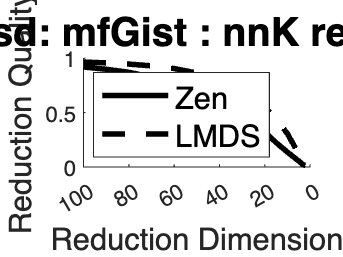

chartDims = - red_dims;

figure;
xticks(min(chartDims): max(red_dims) / 5 : 0);
xticklabels(max(red_dims):-max(red_dims)/5:0);
ylim([0 1]);

hold on;

plot(chartDims,nRes,"-k","LineWidth",2.5);
plot(chartDims,lRes,"--k","LineWidth",2.5);

title(strcat("jsd: ",shortname," : ","nnK recall"),"FontSize",18);
xlabel("Reduction Dimension","FontSize",14);
ylabel("Reduction Quality","FontSize",14);

legend("Zen", ...
    "LMDS", ...
    "Location","southwest","FontSize",14);

hold off;

function ds = doExperiment(data,queries,nnsForTest,projDim,projection,metric,groundtruth,refDists)
allDs = getStats(data,queries,nnsForTest,projDim,projection,metric,groundtruth,refDists);

ds = mean(allDs);

end


function ds = getStats(data,queries,depth,projDim,projection,metric,groundtruth,refDists)

% so this call for LMDS requires 1M * no of landmark points distance calcs
% so this is v expensive, but only needs to be done once for all iterations
% of different dimensions...
projected = projectData(data,projDim,projection,refDists);
noOfQs = size(queries,1);
ds = zeros(noOfQs,1);

for i = 1 : noOfQs

    % nn_brute calculates the rankings of the data in terms of closeness to
    % the given query, this should be passed in as the query ground truth
    i1 = groundtruth(:,i);

    pq = projection.project(queries(i,:));

    [~,i2] = nn_brute(projected,pq,depth,metric);

    ds(i) = dcg2(i1,i2);
end
end

function ps = projectData(data,projDim,projection,refDists)

datasize = size(data,1);
ps = zeros(datasize,projDim);
for i = 1 : datasize
    try
        % only nsimp and lmds have this, doesn't make sense otherwise
        ps(i,:) = projection.projectWithDistances((refDists(i,1:200))');
    catch
        ps(i,:) = projection.project(data(i,:));
    end
end
end

function res = dcg2(i1,i2)
%i1 and i2 are the nearest neighbour indexes into original and projected
%data in order of closeness

% CG at n: \sum_{k=1}^n(v_k) where v_k is the value of the object at k
% discounted: divide each v_k by log_2(k+1)
% can also put 2^{v_k}-1 on the top line
sz = length(i1);
res = 0;
for i = 1 : length(i2) %go down the DR-returned nn list
    % is the ith DR result in the true list?
    % if so its in the r-th place
    r = find(i2(i) == i1);
    if not(isempty(r)) %if it's not, there is nothing to do as its relevance is zero
        % how far down the list are we here, for the bottom line?
        logrank = log2(i + 1);

        rel_r = value(r,sz); %this is the relevance calc for rth place
        res = res + (2^rel_r - 1) / logrank;
    end
end
res = res / 66.0435;
end

% function v = value(nn,max)
% %need to assign a relevance value to each nn
% v = sqrt((max + 1 - nn) / max);
% end

function r = value(i,n)
f1 = (n + 1 - i);
f2 = n / 10;
f3 = ( f1 - (n/2));
r = 1 ./(1 + exp(-f3/100));
end

function ranking = getGroundTruth(data,queries,kNN,metric)
noOfQueries = size(queries,1);
ranking = zeros(kNN,noOfQueries);
for i = 1 : noOfQueries
    [~,rank] = nn_brute(data,queries(i,:),kNN,metric);
    ranking(:,i) = rank;
end
end